PARÂMETROS DO SWING-UP


Energia inferior Ebaixo     = -0.97708 J


Energia do topo Etopo       = 0 J


DeltaE                     = 0.97708 J


Excesso de energia         = 15 %


Energia desejada Eref      = 0.14656 J


kSwing calculado           = 12.2815 V/J


Polaridade do swing-up     = -1


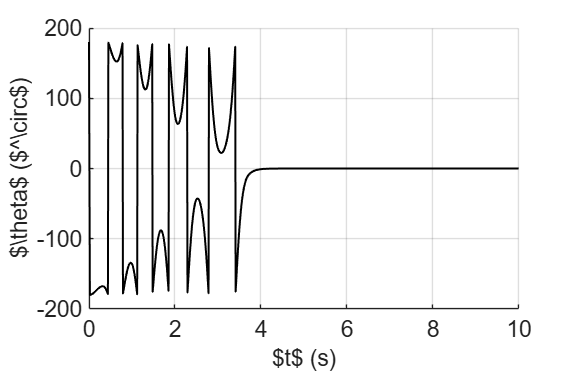

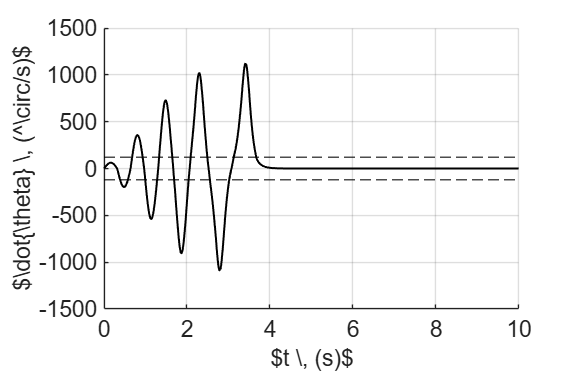

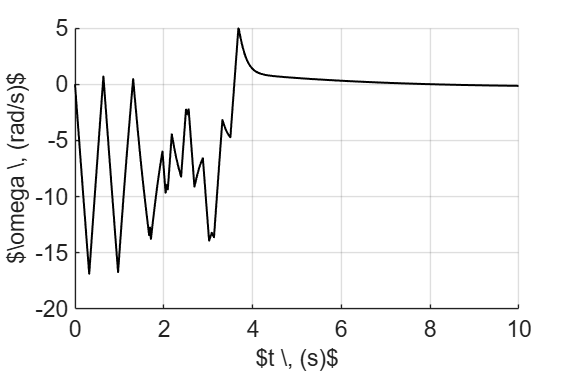

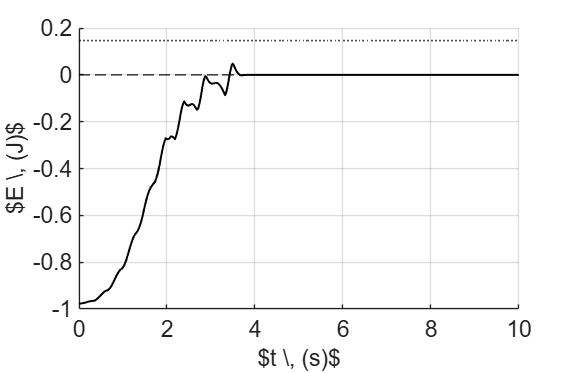

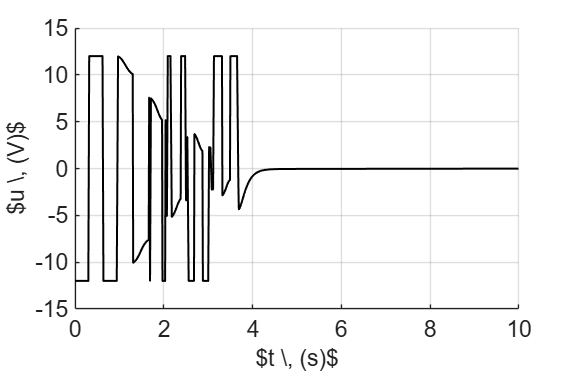

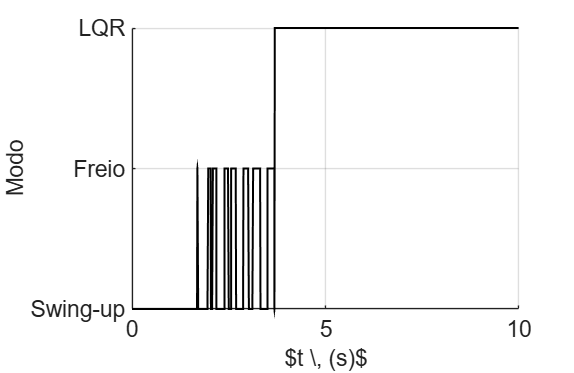

Simulação concluída.


PDFs gerados individualmente com sucesso.


% =========================================================================
%  Simulação do controle swing-up com comutação para LQR
% =========================================================================
%
%  Este script realiza a validação numérica da estratégia de elevação do
%  triângulo autoequilibrante. A simulação considera inicialmente a planta
%  em uma condição afastada da posição vertical e aplica uma lei de controle
%  swing-up baseada em energia para aumentar a amplitude de oscilação do
%  sistema.
%
%  Quando a planta entra na região de captura definida pelos limites de
%  ângulo e velocidade angular, o algoritmo realiza a comutação para o
%  controlador LQR discreto. Caso a planta esteja próxima da posição vertical,
%  mas ainda apresente velocidade angular elevada, é aplicado um modo
%  intermediário de frenagem antes da entrada no LQR.
%
%  O código utiliza os parâmetros físicos e eletromecânicos da planta,
%  discretiza o modelo aumentado pelo método de Tustin, executa a simulação
%  dos modos swing-up, freio e LQR, e gera individualmente os gráficos em
%  formato PDF para utilização na monografia.
%
%  Saídas geradas:
%    - resultado_theta_simulado.pdf
%    - resultado_theta_dot_simulado.pdf
%    - resultado_omega_simulado.pdf
%    - resultado_energia_simulado.pdf
%    - resultado_controle_simulado.pdf
%    - resultado_modo_simulado.pdf
%
% =========================================================================

clc;
clear;
close all;

%% Parâmetros físicos da planta

m  = 0.498;
g  = 9.81;
l  = 0.10;
I  = 0.00498;

mw = 0.117;
Rw = 0.126;
Iw = 9.28746e-4;

k  = 0.02938;
r  = 7.0518;

%% Modelo linear em espaço de estados

A = [0         1        0;
     m*g*l/I   0        k^2/(I*r);
     0         0       -k^2/(Iw*r)];

B = [0;
    -k/(I*r);
     k/(Iw*r)];

Aa = [A      zeros(3,1);
      0 0 -1 0];

Ba = [B;
      0];

%% Discretização do modelo aumentado

Ts = 0.01;

sysc = ss(Aa, Ba, eye(4), zeros(4,1));
sysd = c2d(sysc, Ts, 'tustin');

Ad = sysd.A;
Bd = sysd.B;

%% Ganho LQR discreto

Kd = [-247.8615  -26.3120  -0.1175   0.0107];

%% Parâmetros do controle swing-up por energia

uMax = 12;

Ebaixo = -2*m*g*l;
Etopo = 0;
DeltaE = abs(Ebaixo - Etopo);

excessoEnergia = 0.15;
Eref = Etopo + excessoEnergia*DeltaE;

kSwing = uMax / DeltaE;

polaridadeSwing = -1;

%% Critérios de captura e comutação

thetaLQR    = deg2rad(12);
thetaDotLQR = deg2rad(120);

thetaCaptura = deg2rad(90);

%% Configuração da simulação

Tsim = 10;
N = round(Tsim/Ts);

t = (0:N-1)*Ts;

x = zeros(4,N);
u = zeros(1,N);
E = zeros(1,N);
modo = zeros(1,N);

x(:,1) = [pi; 0; 0; 0];

lqrAtivo = false;

%% Simulação dos modos de operação

for i = 1:N-1

    theta    = x(1,i);
    thetaDot = x(2,i);
    omega    = x(3,i);
    xi       = x(4,i);

    % Mantém o ângulo no intervalo entre -pi e pi.
    theta = atan2(sin(theta), cos(theta));
    x(1,i) = theta;

    % Energia mecânica tomando a posição vertical superior como referência.
    E(i) = 0.5*I*thetaDot^2 + m*g*l*(cos(theta) - 1);

    % Verifica se a planta atende aos critérios para entrada no LQR.
    if ~lqrAtivo
        if abs(theta) < thetaLQR && abs(thetaDot) < thetaDotLQR
            lqrAtivo = true;

            % Reinicia o estado associado à roda no instante de comutação.
            x(4,i) = 0;
            xi = 0;
        end
    end

    % Calcula o sinal de controle conforme o modo ativo.
    if lqrAtivo

        % Modo LQR: estabilização em torno da posição vertical.
        u(i) = -Kd*x(:,i);

        modo(i) = 2;

    else

        if abs(theta) < thetaCaptura && abs(thetaDot) >= thetaDotLQR

            % Modo de freio: redução da velocidade angular antes da captura.
            u(i) = uMax * sign(thetaDot);

            modo(i) = 1;

        else

            % Modo swing-up: controle de energia para elevação da planta.
            erroE = E(i) - Eref;

            sinal = sign(thetaDot);

            if sinal == 0
                sinal = sign(theta);
            end

            if sinal == 0
                sinal = 1;
            end

            u(i) = -polaridadeSwing * kSwing * erroE * sinal;

            modo(i) = 0;

        end

    end

    % Saturação do sinal de controle na faixa de operação do motor.
    u(i) = max(min(u(i), uMax), -uMax);

    % Atualização dos estados da planta.
    if lqrAtivo

        % Modelo discreto aumentado utilizado após a comutação para o LQR.
        x(:,i+1) = Ad*x(:,i) + Bd*u(i);

    else

        % Modelo não linear utilizado durante o swing-up e o modo de freio.
        thetaDDot = (m*g*l/I)*sin(theta) + ...
                    (k^2/(I*r))*omega - ...
                    (k/(I*r))*u(i);

        omegaDot = -(k^2/(Iw*r))*omega + ...
                    (k/(Iw*r))*u(i);

        xiDot = -omega;

        x(1,i+1) = x(1,i) + Ts*x(2,i);
        x(2,i+1) = x(2,i) + Ts*thetaDDot;
        x(3,i+1) = x(3,i) + Ts*omegaDot;
        x(4,i+1) = x(4,i) + Ts*xiDot;

    end

end

E(end) = E(end-1);
u(end) = u(end-1);
modo(end) = modo(end-1);

%% Exibição dos parâmetros do controle swing-up

disp('===============================================');
disp('PARÂMETROS DO SWING-UP');
disp('===============================================');
disp(['Energia inferior Ebaixo     = ', num2str(Ebaixo), ' J']);
disp(['Energia do topo Etopo       = ', num2str(Etopo), ' J']);
disp(['DeltaE                     = ', num2str(DeltaE), ' J']);
disp(['Excesso de energia         = ', num2str(excessoEnergia*100), ' %']);
disp(['Energia desejada Eref      = ', num2str(Eref), ' J']);
disp(['kSwing calculado           = ', num2str(kSwing), ' V/J']);
disp(['Polaridade do swing-up     = ', num2str(polaridadeSwing)]);
disp('===============================================');

%% Configuração gráfica para exportação

theta_graus = rad2deg(x(1,:));
thetaDot_graus = rad2deg(x(2,:));

picturewidth = 20;
hw_ratio = 0.65;

%% Figura 1 - Ângulo da planta

hfig = figure;

plot(t, theta_graus, 'k-', 'LineWidth', 1.5);

xlabel('$t$ (s)', 'Interpreter', 'latex');
ylabel('$\theta$ ($^\circ$)', 'Interpreter', 'latex');

grid on;

fname = 'resultado_theta_simulado';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 2 - Velocidade angular do corpo

hfig = figure;

plot(t, thetaDot_graus, 'k-', 'LineWidth', 1.5);
hold on;
yline(rad2deg(thetaDotLQR), '--k', 'Limite LQR', 'LineWidth', 1.2);
yline(-rad2deg(thetaDotLQR), '--k', 'Limite LQR', 'LineWidth', 1.2);
hold off;

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\dot{\theta} \, (^\circ/s)$', 'Interpreter', 'latex');

grid on;

fname = 'resultado_theta_dot_simulado';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 3 - Velocidade angular da roda de reação

hfig = figure;

plot(t, x(3,:), 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$\omega \, (rad/s)$', 'Interpreter', 'latex');

grid on;

fname = 'resultado_omega_simulado';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 4 - Energia mecânica

hfig = figure;

plot(t, E, 'k-', 'LineWidth', 1.5);
hold on;
yline(Etopo, '--k', '$E_{topo}$', 'LineWidth', 1.2, 'Interpreter', 'latex');
yline(Eref, ':k', '$E_{ref}$', 'LineWidth', 1.2, 'Interpreter', 'latex');
hold off;

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$E \, (J)$', 'Interpreter', 'latex');

grid on;

fname = 'resultado_energia_simulado';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 5 - Sinal de controle

hfig = figure;

plot(t, u, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('$u \, (V)$', 'Interpreter', 'latex');

grid on;

fname = 'resultado_controle_simulado';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

%% Figura 6 - Modo de controle

hfig = figure;

stairs(t, modo, 'k-', 'LineWidth', 1.5);

xlabel('$t \, (s)$', 'Interpreter', 'latex');
ylabel('Modo', 'Interpreter', 'latex');

yticks([0 1 2]);
yticklabels({'Swing-up', 'Freio', 'LQR'});

grid on;

fname = 'resultado_modo_simulado';

set(findall(hfig, '-property', 'FontSize'), 'FontSize', 17)
set(findall(hfig, '-property', 'Box'), 'Box', 'off')
set(findall(hfig, '-property', 'Interpreter'), 'Interpreter', 'latex')
set(findall(hfig, '-property', 'TickLabelInterpreter'), 'TickLabelInterpreter', 'latex')

set(hfig, 'Units', 'centimeters', ...
    'Position', [3 3 picturewidth hw_ratio*picturewidth])

pos = get(hfig, 'Position');

set(hfig, 'PaperPositionMode', 'Auto', ...
    'PaperUnits', 'centimeters', ...
    'PaperSize', [pos(3), pos(4)])

print(hfig, fname, '-dpdf', '-vector')

disp('Simulação concluída.');
disp('PDFs gerados individualmente com sucesso.');